# Laboratorio 3 - Modelo diferencial de primer orden

#### Grupo 8

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

Nuestro robot: Fanuc R-2000iC/125L

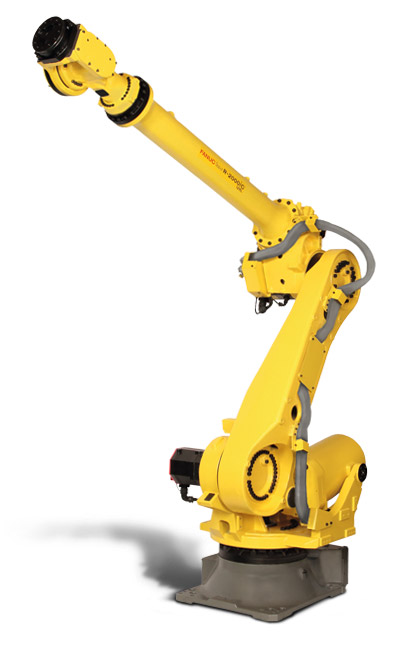

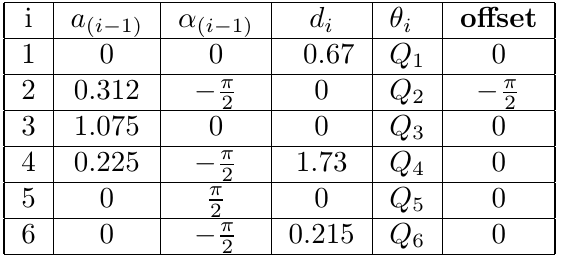

- Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numéricos, NO simbólicos) en función de los ángulos de articulación. 

La de arriba es la tabla de DH mod, para esta lab utilizaremos la DH estándar:

L(1) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0.67, 'offset',0,  ...
    'standard', 'qlim',[-pi pi]);

Unable to perform assignment because value of type 'Link' is not convertible to 'double'.

Caused by:
    Error using double
    Conversion to double from Link is not possible.

L(2) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',-pi/2,...
    'standard', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',pi/2, 'a', 0,    'd',1.73, 'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha',-pi/2,'a', 0,    'd',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',0,    'a', 0,    'd',0.215,'offset',0, ...
    'standard', 'qlim',[-pi pi]);

Robot = SerialLink(L,'name','R_{Fanuc}')

%Posición de las articulaciones del robot
q = [0 pi/2 0 -pi/2 0 0];

A_0_1 = L(1).A(q(1))
A_1_2 = L(2).A(q(2))
A_2_3 = L(3).A(q(3))
A_3_4 = L(4).A(q(4))
A_4_5 = L(5).A(q(5))
A_5_6 = L(6).A(q(6))

%Valores absolutos de 1 a 6
T_0_1 = A_0_1 * eye(4)
T_0_2 = A_0_1 * A_1_2 * eye(4)
T_0_3 = A_0_1 * A_1_2 * A_2_3 * eye(4)
T_0_4 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * eye(4)
T_0_5 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * eye(4)
T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 * eye(4)

%Las Z
Z_0 = [0; 0; 1]
Z_1 = [T_0_1(1,3); T_0_1(2,3); T_0_1(3,3)]
Z_2 = [T_0_2(1,3); T_0_2(2,3); T_0_2(3,3)]
Z_3 = [T_0_3(1,3); T_0_3(2,3); T_0_3(3,3)]
Z_4 = [T_0_4(1,3); T_0_4(2,3); T_0_4(3,3)]
Z_5 = [T_0_5(1,3); T_0_5(2,3); T_0_5(3,3)]

%Posiciones absolutas de los sistemas de referencia
T_0 = [0; 0; 0]
T_1 = [T_0_1(1,4); T_0_1(2,4); T_0_1(3,4)]
T_2 = [T_0_2(1,4); T_0_2(2,4); T_0_2(3,4)]
T_3 = [T_0_3(1,4); T_0_3(2,4); T_0_3(3,4)]
T_4 = [T_0_4(1,4); T_0_4(2,4); T_0_4(3,4)]
T_5 = [T_0_5(1,4); T_0_5(2,4); T_0_5(3,4)]
T_6 = [T_0_6(1,4); T_0_6(2,4); T_0_6(3,4)]

%Jacobiano
J = [cross(Z_0,(T_6-T_0)) cross(Z_1,(T_6-T_1)) cross(Z_2,(T_6-T_2))...
    cross(Z_3,(T_6-T_3)) cross(Z_4,(T_6-T_4)) cross(Z_5,(T_6-T_5));
    Z_0 Z_1 Z_2 Z_3 Z_4 Z_5]

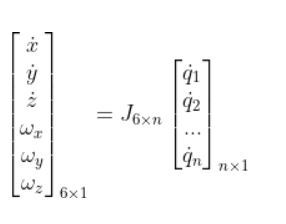

Ya se obtuvo el Jacobiano, ahora toca obtener el inverso.

Ahora para el punto 2. Para una postura de su elección dentro del espacio diestro del robot obtenga las velocidades de articulación para:

Como nuestro Jacobiano es cuadrado simplemente se encuentra el inverso del jacobiano de manera tradicional.

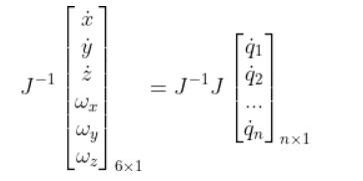

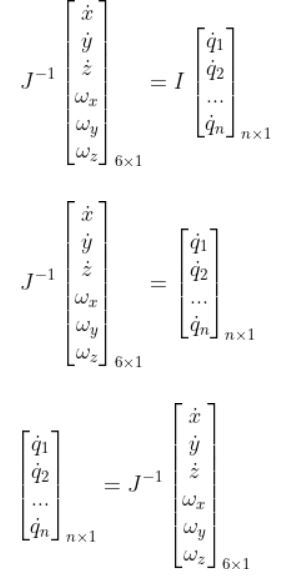

Jinv = pinv(J)

Para obtener la respuesta con los valores propuestos luego hacemos:

V_H = [100;200;50]
w_H = [5;10;-5]
vector = [V_H;w_H]
q_punto = Jinv*vector

Ubique la ruta seleccionada con la orientaci´on indicada dentro del espacio diestro del robot

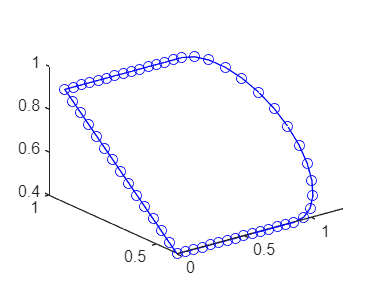

horizontal = 3.1;
L = 0.4*horizontal;

r = 0.3*L;
n = 15;

t1 = [linspace(0,L-r,n)' zeros(n,2)];
theta = linspace(-pi/2,pi/2, n);
cx = (L-r);
cy = r;
cz = 0;

t2 = [cx+r*cos(theta)' cy+r*sin(theta)' cz+0.*theta'];
t3 = [t2(end,:);linspace(L-r,0,n)' 2*r.*ones(n,1) zeros(n,1)];
t4 = [t3(end,:);zeros(n,1) linspace(2*r,0,n)' zeros(n,1)];

ruta = [t1; t2; t3; t4];

clf
R0_t = rotx(45,'deg');
p0_t = [0 0.4 0.4];
ruta_ = 0.*ruta;
for i=1:length(ruta(:,1))
    ruta_(i,:) = R0_t*ruta(i,:)'+p0_t';
end

figure (1)
plot3(ruta_(:,1),ruta_(:,2),ruta_(:,3),'-bo')

Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articulación al recorrer la ruta.

Para esto se crea el robot con el RST

robot = rigidBodyTree;
body1 = rigidBody('body1'); 
body2 = rigidBody('body2'); 
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
bodyEndEffector=rigidBody('endeffector');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');
%body1
tform1 = transl(0, 0, 0.67);
setFixedTransform(jnt1,tform1); 
body1.Joint = jnt1;
addBody(robot,body1,'base')

%body2
tform2 = transl(0.312, 0, 0)*trotx(-pi/2)*trotz(-pi/2);
setFixedTransform(jnt2,tform2);
%setFixedTransform(jnt2,dhparams(2,:),'dh'); 
body2.Joint = jnt2;
addBody(robot,body2,'body1')

%body3
tform3 = transl(1.075, 0, 0);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2')

%body4
tform4 = transl(0.225, 1.73, 0)*trotx(-pi/2);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3')

%body5
tform5 = transl(0, 0, 0)*trotx(pi/2);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4')

%body6
tform6 = transl(0, 0.215, 0)*trotx(-pi/2);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5')

%endEffector
tform7 = trvec2tform([0 0 0]);
setFixedTransform(bodyEndEffector.Joint,tform7);
addBody(robot,bodyEndEffector,'body6')

Ahora la cinemática inversa

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = homeConfiguration(robot);
robot.BodyNames

ans = 1×7 cell array
    {'body1'}    {'body2'}    {'body3'}    {'body4'}    {'body5'}    {'body6'}    {'endeffector'}



viapoints = length(ruta(:,1));
conf_ruta = zeros(viapoints,6);
for i=1:viapoints
    tic
    if i>1
        initialguess = configSoln;
    end
    p0_t = ruta_(i,:);
    R0_t = rotx(-135,'deg');
    MTHpose = [R0_t p0_t'; 0 0 0 1];
    [configSoln,solnInfo] = ik('endeffector',MTHpose,weights,initialguess);
    conf_ruta(i,:) = [configSoln(1).JointPosition configSoln(2).JointPosition configSoln(3).JointPosition ...
        configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
    disp(strcat(num2str(i),"/",num2str(viapoints)))
    toc
end

1/62


Elapsed time is 2.015810 seconds.


2/62


Elapsed time is 1.346677 seconds.


3/62


Elapsed time is 1.542609 seconds.


4/62


Elapsed time is 1.500171 seconds.


5/62


Elapsed time is 0.051974 seconds.


6/62


Elapsed time is 0.024887 seconds.


7/62


Elapsed time is 0.020022 seconds.


8/62


Elapsed time is 0.022952 seconds.


9/62


Elapsed time is 0.018234 seconds.


10/62


Elapsed time is 0.018576 seconds.


11/62


Elapsed time is 0.020320 seconds.


12/62


Elapsed time is 0.023707 seconds.


13/62


Elapsed time is 0.020724 seconds.


14/62


Elapsed time is 0.023883 seconds.


15/62


Elapsed time is 0.018079 seconds.


16/62


Elapsed time is 0.002304 seconds.


17/62


Elapsed time is 0.018044 seconds.


18/62


Elapsed time is 0.020019 seconds.


19/62


Elapsed time is 0.068987 seconds.


20/62


Elapsed time is 0.019267 seconds.


21/62


Elapsed time is 0.020525 seconds.


22/62


Elapsed time is 0.023306 seconds.


23/62


Elapsed time is 0.019350 seconds.


24/62


Elapsed time is 0.018361 seconds.


25/62


Elapsed time is 0.019261 seconds.


26/62


Elapsed time is 0.019651 seconds.


27/62


Elapsed time is 0.026566 seconds.


28/62


Elapsed time is 0.052287 seconds.


29/62


Elapsed time is 0.026007 seconds.


30/62


Elapsed time is 0.023412 seconds.


31/62


Elapsed time is 0.003786 seconds.


32/62


Elapsed time is 0.003672 seconds.


33/62


Elapsed time is 0.019238 seconds.


34/62


Elapsed time is 0.023183 seconds.


35/62


Elapsed time is 0.020721 seconds.


36/62


Elapsed time is 0.026168 seconds.


37/62


Elapsed time is 0.025826 seconds.


38/62


Elapsed time is 0.025796 seconds.


39/62


Elapsed time is 0.021168 seconds.


40/62


Elapsed time is 0.026632 seconds.


41/62


Elapsed time is 0.023267 seconds.


42/62


Elapsed time is 0.020721 seconds.


43/62


Elapsed time is 0.023245 seconds.


44/62


Elapsed time is 0.021101 seconds.


45/62


Elapsed time is 0.026936 seconds.


46/62


Elapsed time is 0.022428 seconds.


47/62


Elapsed time is 0.002185 seconds.


48/62


Elapsed time is 0.002039 seconds.


49/62


Elapsed time is 0.018173 seconds.


50/62


Elapsed time is 0.017701 seconds.


51/62


Elapsed time is 0.017107 seconds.


52/62


Elapsed time is 0.019041 seconds.


53/62


Elapsed time is 0.020143 seconds.


54/62


Elapsed time is 0.021552 seconds.


55/62


Elapsed time is 0.033355 seconds.


56/62


Elapsed time is 0.023061 seconds.


57/62


Elapsed time is 0.019454 seconds.


58/62


Elapsed time is 0.015376 seconds.


59/62


Elapsed time is 0.020092 seconds.


60/62


Elapsed time is 1.853717 seconds.


61/62


Elapsed time is 1.782341 seconds.


62/62


Elapsed time is 1.657155 seconds.


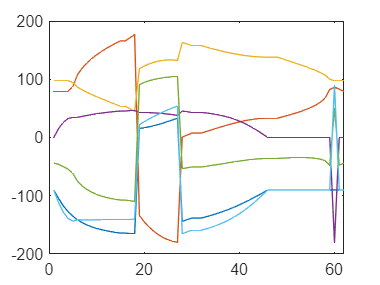


figure (2)
plot(conf_ruta(:,1)*180/pi)
hold on
plot(conf_ruta(:,2)*180/pi)
hold on
plot(conf_ruta(:,3)*180/pi)
hold on
plot(conf_ruta(:,4)*180/pi)
hold on
plot(conf_ruta(:,5)*180/pi)
hold on
plot(conf_ruta(:,6)*180/pi)
hold off